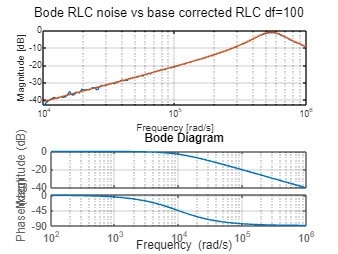

clear 
clc

%RC filter parameters
R1 = 47; %ohm
C1 = 2.2*10^-6; %farad
%RLC filter parameters
R2 = 220; %ohm
C2 = 4.7*10^-9; %farad
L2 = 1*10^-3; %henry
%RC excitation signals
y11 = load("20210305-RC_Chirp40v150kHz_T2s.mat");
%cleaning the data
A11 = y11.A;
B11 = y11.B;
A11(isnan(A11)) = 0;
B11(isnan(B11)) = 0;
A11(isinf(A11)) = 0;
B11(isinf(B11)) = 0;
y12 = load("20210305-RC_SzumBand200kHz_T2s.mat");
A12 = y12.A;
B12 = y12.B;
A12(isnan(A12)) = 0;
B12(isnan(B12)) = 0;
A12(isinf(A12)) = 0;
B12(isinf(B12)) = 0;
%RLC excitation signals
y21 = load("20220401-RLC_Chirp1v300kHz_T2s.mat");
A21 = y21.A;
B21 = y21.B;
A21(isnan(A21)) = 0;
B21(isnan(B21)) = 0;
A21(isinf(A21)) = 0;
B21(isinf(B21)) = 0;
y22 = load("20220401-RLC_SzumBand500kHz_T2.mat");
A22 = y22.A;
B22 = y22.B;
A22(isnan(A22)) = 0;
B22(isnan(B22)) = 0;
A22(isinf(A22)) = 0;
B22(isinf(B22)) = 0;
%RC filter
Y1=[1/(R1*C1)];
V1=[1 1/(R1*C1)];
sys1=tf(Y1,V1);
%RLC filter
Y2=[R2/L2 0];
V2=[1 R2/L2 1/(C2*L2)];
sys2=tf(Y2,V2);
%bode plot of the RC system
[mag1,phase1,w1]=bode(sys1);
mag1=squeeze(mag1);
phase1=squeeze(phase1);
bode(sys1), grid on

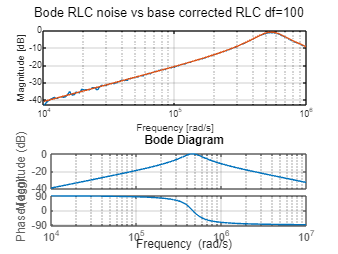

%bode plot of the RLC system
[mag2,phase2,w2]=bode(sys2);
bode(sys2), grid on

mag2=squeeze(mag2);
phase2=squeeze(phase2);

%finding resonant frequency and damping (half power method) for RLC

omega1 = 364607;
omega2 = 583643;
omegar = 457801;
damping = (omega2-omega1)/(2*omegar)

damping = 0.2392


omega12 = 436763;
omega22 = 542537;
omegar2 = 672156;
damping2 = (omega22-omega12)/(2*omegar2)

damping2 = 0.0787

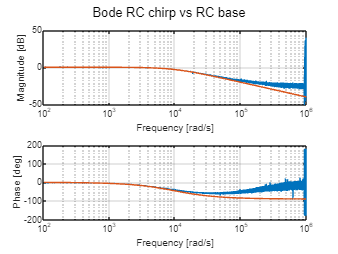



%plotting bode for the acquired signal (RC) chirp
fA11=fft(A11);
fB11 = fft(B11);
H11 = fA11./fB11;
N11=length(H11);
f11=2*pi*1/y11.Tinterval*(0:(N11-1))/N11;
mag_sys11=abs(H11);
phase_deg11=rad2deg(angle(H11));

% figure()
% subplot(2,1,1);
% semilogx(f11,20*log10(mag_sys11)), grid on
% xlabel('Frequency [rad/s]')
% ylabel('Magnitude [dB]')
% subplot(2,1,2);
% semilogx(f11,phase_deg11), grid on
% xlabel('Frequency [rad/s]')
% ylabel('Phase [deg]')
% sgtitle('Bode RC chirp')

%plotting bode RC noise
fA12=fft(A12);
fB12 = fft(B12);
H12 = fA12./fB12;
N12=length(H12);
f12=2*pi*1/y12.Tinterval*(0:(N12-1))/N12;
mag_sys12=abs(H12);
phase_deg12=rad2deg(angle(H12));

% figure()
% subplot(2,1,1);
% semilogx(f12,20*log10(mag_sys12)), grid on
% xlabel('Frequency [rad/s]')
% ylabel('Magnitude [dB]')
% subplot(2,1,2);
% semilogx(f12,phase_deg12), grid on
% xlabel('Frequency [rad/s]')
% ylabel('Phase [deg]')
% sgtitle('Bode RC noise')

%plotting bode for the acquired signal (RLC) chirp
fA21=fft(A21);
fB21 = fft(B21);
H21 = fA21./fB21;
N21=length(H21);
f21=2*pi*1/y21.Tinterval*(0:(N21-1))/N21;
mag_sys21=abs(H21);
phase_deg21=rad2deg(angle(H21));

% figure()
% subplot(2,1,1);
% semilogx(f21,20*log10(mag_sys21)), grid on
% xlabel('Frequency [rad/s]')
% ylabel('Magnitude [dB]')
% subplot(2,1,2);
% semilogx(f21,phase_deg21), grid on
% xlabel('Frequency [rad/s]')
% ylabel('Phase [deg]')
% sgtitle('Bode RLC chirp')

%plotting bode for RLC noise
fA22=fft(A22);
fB22 = fft(B22);
H22 = fA22./fB22;
N22=length(H22);
f22=2*pi*1/y22.Tinterval*(0:(N22-1))/N22;
mag_sys22=abs(H22);
phase_deg22=rad2deg(angle(H22));

% figure()
% subplot(2,1,1);
% semilogx(f22,20*log10(mag_sys22)), grid on
% xlabel('Frequency [rad/s]')
% ylabel('Magnitude [dB]')
% subplot(2,1,2);
% semilogx(f22,phase_deg22), grid on
% xlabel('Frequency [rad/s]')
% ylabel('Phase [deg]')
% sgtitle('Bode RLC noise')


figure()
subplot(2,1,1);
semilogx(f11,20*log10(mag_sys11)), grid on, hold on
semilogx(w1, 20*log10(mag1)), hold off
xlim([10^2 10^6])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f11,phase_deg11), grid on, hold on
semilogx(w1,phase1)
xlim([10^2 10^6])
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')
sgtitle('Bode RC chirp vs RC base')

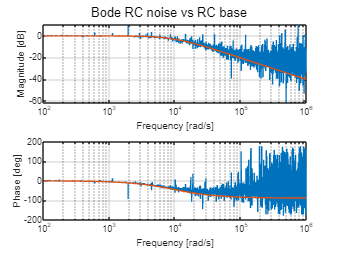


figure()
subplot(2,1,1);
semilogx(f12,20*log10(mag_sys12)), grid on, hold on
semilogx(w1, 20*log10(mag1)), hold off
xlim([10^2 10^6])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f12,phase_deg12), grid on, hold on
semilogx(w1,phase1)
xlim([10^2 10^6])
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')
sgtitle('Bode RC noise vs RC base')

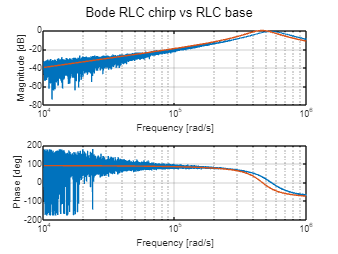


figure()
subplot(2,1,1);
semilogx(f21,20*log10(mag_sys21)), grid on, hold on
semilogx(w2, 20*log10(mag2)), hold off
xlim([10^4 10^6])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f21,phase_deg21), grid on, hold on
semilogx(w2, phase2), hold off
xlim([10^4 10^6])
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')
sgtitle('Bode RLC chirp vs RLC base')

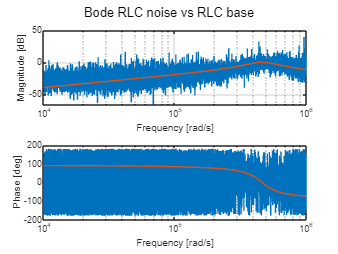


figure()
subplot(2,1,1);
semilogx(f22,20*log10(mag_sys22)), grid on, hold on
semilogx(w2, 20*log10(mag2)), hold off
xlim([10^4 10^6])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f22,phase_deg22), grid on, hold on
semilogx(w2, phase2), hold off
xlim([10^4 10^6])
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')
sgtitle('Bode RLC noise vs RLC base')

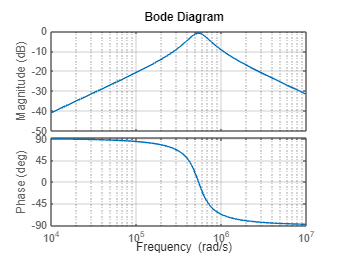


%creating the corrected system
R2=217;
C2=4.1*10^-9;
L2=0.83*10^-3;
R2L=25;
Ind=15.4;

%corrected RLC filter
Y2=[R2/L2 0];
V2=[1 (R2+R2L)/L2 1/(C2*L2)];
sys3=tf(Y2,V2);

%corrected RC filter
Y3=[1/(R1*C1)];
V3=[1 1/(R1*C1)];
sys4=tf(Y3,V3);

%bode plot of the corrected RLC system
[mag3,phase3,w3]=bode(sys3);
figure()
bode(sys3), grid on

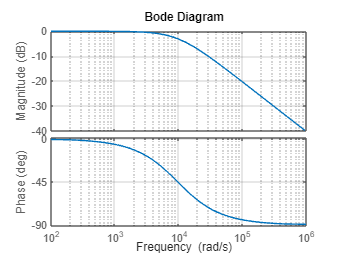

%squeezing the results for plotting
mag3=squeeze(mag3);
phase3=squeeze(phase3);

%bode plot of the corrected RLC system
[mag4,phase4,w4]=bode(sys4);
figure()
bode(sys4), grid on

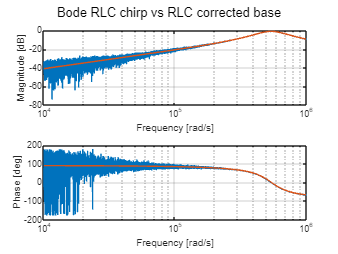

%squeezing the results for plotting
mag4=squeeze(mag4);
phase4=squeeze(phase4);

%comparing with the chirp
figure()
subplot(2,1,1);
semilogx(f21,20*log10(mag_sys21)), grid on, hold on
semilogx(w3, 20*log10(mag3)), hold off
xlim([10^4 10^6])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f21,phase_deg21), grid on, hold on
semilogx(w3, phase3), hold off
xlim([10^4 10^6])
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')
sgtitle('Bode RLC chirp vs RLC corrected base')

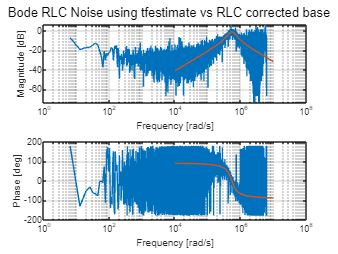


df = 1;
dt=y22.Tinterval; %timestep given in the data
fs=1/dt;
window = round(fs/df); %from df=fs/N
overlap = round(window / 2); %50% means half of the window
nfft = window;
[H3,F] = tfestimate(B22,A22,window,overlap,nfft,fs,'twosided');

F=F';
N3=length(H3);
f3=2*pi*1/y22.Tinterval*(0:(N3-1))/N3;
mag_sys3=abs(H3);
phase_deg3=rad2deg(angle(H3));

figure()
subplot(2,1,1);
semilogx(f3,20*log10(mag_sys3)), grid on, hold on
semilogx(w3, 20*log10(mag3)), hold off
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f3,phase_deg3), grid on, hold on
semilogx(w3, phase3), hold off
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')
sgtitle('Bode RLC Noise using tfestimate vs RLC corrected base')

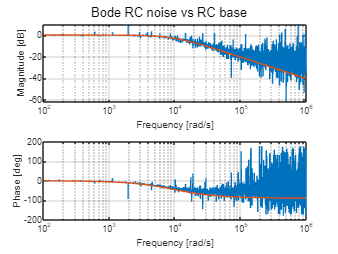



figure()
subplot(2,1,1);
semilogx(f12,20*log10(mag_sys12)), grid on, hold on
semilogx(w1, 20*log10(mag1)), hold off
xlim([10^2 10^6])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f12,phase_deg12), grid on, hold on
semilogx(w1,phase1)
xlim([10^2 10^6])
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')
sgtitle('Bode RC noise vs RC base')

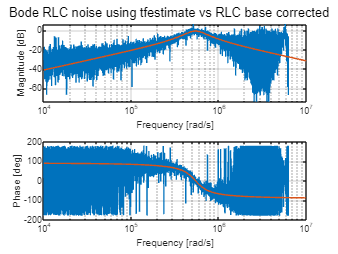


figure()
subplot(2,1,1);
semilogx(f3,20*log10(mag_sys3)), grid on, hold on
semilogx(w3, 20*log10(mag3)), hold off
xlim([10^4 10^7])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f3,phase_deg3), grid on, hold on
semilogx(w3, phase3), hold off
xlim([10^4 10^7])
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')
sgtitle('Bode RLC noise using tfestimate vs RLC base corrected')

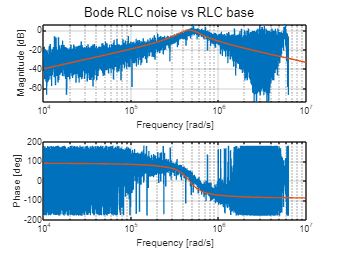

figure()
subplot(2,1,1);
semilogx(f3,20*log10(mag_sys3)), grid on, hold on
semilogx(w2, 20*log10(mag2)), hold off
xlim([10^4 10^7])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f3,phase_deg3), grid on, hold on
semilogx(w2, phase2), hold off
xlim([10^4 10^7])
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')
sgtitle('Bode RLC noise vs RLC base')

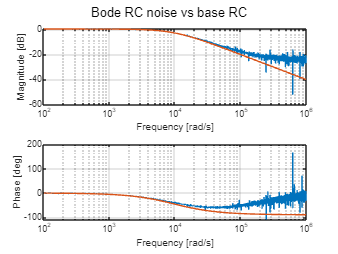



df = 1;
dt=y12.Tinterval; %timestep given in the data
fs=1/dt;
window = round(fs/df); %from df=fs/N
overlap = round(window / 2); %50% means half of the window
nfft = window;
[H4,F2] = tfestimate(B12,A12,window,overlap,nfft,fs,'twosided');
F2=F2';
N4=length(H4);
f4=2*pi*1/y12.Tinterval*(0:(N4-1))/N4;
mag_sys4=abs(H4);
phase_deg4=rad2deg(angle(H4));

figure()
subplot(2,1,1);
semilogx(f4,20*log10(mag_sys4)), grid on, hold on
semilogx(w1, 20*log10(mag1)), hold off
xlim([10^2 10^6])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f4,phase_deg4), grid on, hold on
semilogx(w1, phase1), hold off
xlim([10^2 10^6])
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')
sgtitle('Bode RC noise vs base RC')

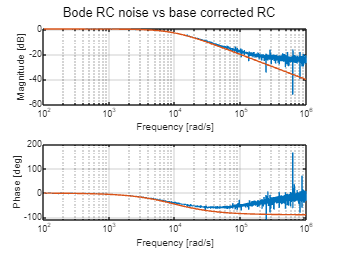

figure()
subplot(2,1,1);
semilogx(f4,20*log10(mag_sys4)), grid on, hold on
semilogx(w4, 20*log10(mag4)), hold off
xlim([10^2 10^6])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f4,phase_deg4), grid on, hold on
semilogx(w4, phase4), hold off
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')
xlim([10^2 10^6])
sgtitle('Bode RC noise vs base corrected RC')

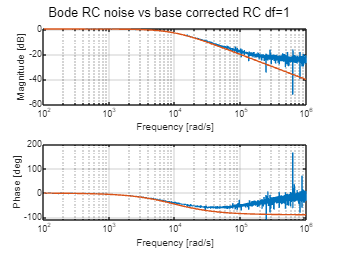


df = 10;
dt=y12.Tinterval; %timestep given in the data
fs=1/dt;
window = round(fs/df); %from df=fs/N
overlap = round(window / 2); %50% means half of the window
nfft = window;
[H5,F3] = tfestimate(B12,A12,window,overlap,nfft,fs,'twosided');
F3=F3';
N5=length(H5);
f5=2*pi*1/y12.Tinterval*(0:(N5-1))/N5;
mag_sys5=abs(H5);
phase_deg5=rad2deg(angle(H5));

df = 100;
dt=y12.Tinterval; %timestep given in the data
fs=1/dt;
window = round(fs/df); %from df=fs/N
overlap = round(window / 2); %50% means half of the window
nfft = window;
[H6,F4] = tfestimate(B12,A12,window,overlap,nfft,fs,'twosided');
F4=F4';
N6=length(H6);
f6=2*pi*1/y12.Tinterval*(0:(N6-1))/N6;
mag_sys6=abs(H6);
phase_deg6=rad2deg(angle(H6));

df = 10;
dt=y22.Tinterval; %timestep given in the data
fs=1/dt;
window = round(fs/df); %from df=fs/N
overlap = round(window / 2); %50% means half of the window
nfft = window;
[H7,F5] = tfestimate(B22,A22,window,overlap,nfft,fs,'twosided');
F5=F5';
N7=length(H7);
f7=2*pi*1/y22.Tinterval*(0:(N7-1))/N7;
mag_sys7=abs(H7);
phase_deg7=rad2deg(angle(H7));

df = 100;
dt=y22.Tinterval; %timestep given in the data
fs=1/dt;
window = round(fs/df); %from df=fs/N
overlap = round(window / 2); %50% means half of the window
nfft = window;
[H8,F6] = tfestimate(B22,A22,window,overlap,nfft,fs,'twosided');
F6=F6';
N8=length(H8);
f8=2*pi*1/y22.Tinterval*(0:(N8-1))/N8;
mag_sys8=abs(H8);
phase_deg8=rad2deg(angle(H8));


figure()
subplot(2,1,1);
semilogx(f4,20*log10(mag_sys4)), grid on, hold on
semilogx(w4, 20*log10(mag4)), hold off
xlim([10^2 10^6])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f4,phase_deg4), grid on, hold on
semilogx(w4, phase4), hold off
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')
xlim([10^2 10^6])
sgtitle('Bode RC noise vs base corrected RC df=1')

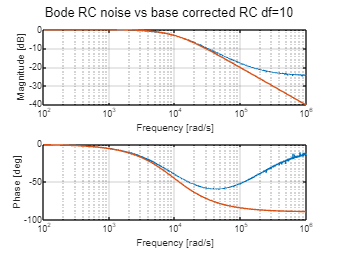


figure()
subplot(2,1,1);
semilogx(f5,20*log10(mag_sys5)), grid on, hold on
semilogx(w4, 20*log10(mag4)), hold off
xlim([10^2 10^6])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f5,phase_deg5), grid on, hold on
semilogx(w4, phase4), hold off
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')
xlim([10^2 10^6])
sgtitle('Bode RC noise vs base corrected RC df=10')

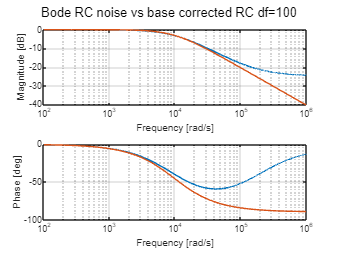


figure()
subplot(2,1,1);
semilogx(f6,20*log10(mag_sys6)), grid on, hold on
semilogx(w4, 20*log10(mag4)), hold off
xlim([10^2 10^6])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f6,phase_deg6), grid on, hold on
semilogx(w4, phase4), hold off
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')
xlim([10^2 10^6])
sgtitle('Bode RC noise vs base corrected RC df=100')

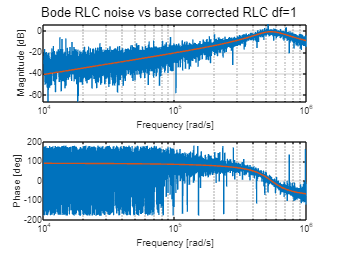



figure()
subplot(2,1,1);
semilogx(f3,20*log10(mag_sys3)), grid on, hold on
semilogx(w3, 20*log10(mag3)), hold off
xlim([10^4 10^6])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f3,phase_deg3), grid on, hold on
semilogx(w3, phase3), hold off
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')
xlim([10^4 10^6])
sgtitle('Bode RLC noise vs base corrected RLC df=1')

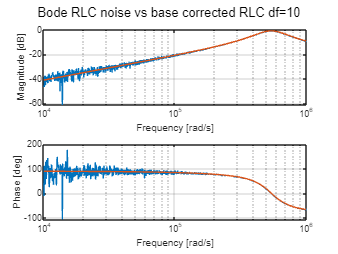


figure()
subplot(2,1,1);
semilogx(f7,20*log10(mag_sys7)), grid on, hold on
semilogx(w3, 20*log10(mag3)), hold off
xlim([10^4 10^6])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f7,phase_deg7), grid on, hold on
semilogx(w3, phase3), hold off
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')
xlim([10^4 10^6])
sgtitle('Bode RLC noise vs base corrected RLC df=10')

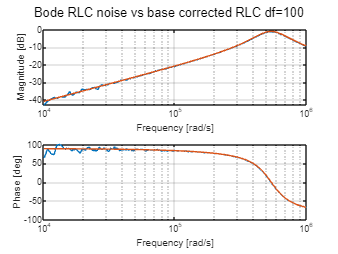


figure()
subplot(2,1,1);
semilogx(f8,20*log10(mag_sys8)), grid on, hold on
semilogx(w3, 20*log10(mag3)), hold off
xlim([10^4 10^6])
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f8,phase_deg8), grid on, hold on
semilogx(w3, phase3), hold off
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')
xlim([10^4 10^6])
sgtitle('Bode RLC noise vs base corrected RLC df=100')